%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## 系统离散化 代码

## 作者：简涛

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## 程序初始化，清空工作空间，缓存，

clear all;
close all;
clc;

## 定义小车倒立摆物理性质

r = 0.075; %车轮的半径
d= 0.4048; %左轮、右轮两个轮子间的距离
l = 0.085; %摆杆质心到转轴距离
m = 0.32; %车轮的质量
M = 10.43; %摆杆质量
I = (1/2)*m*r^2; %车轮的转动惯量
Jz = (1/3)*m*l^2; %机器人机体对 z 轴的运动时产生的转动惯量(俯仰方向)
Jy = (1/12)*m*d^2; %机器人机体对 y 轴的运动时产生的转动惯量(偏航方向)
g = 9.8; %重力加速度b = 1e-4;

## 状态空间矩阵

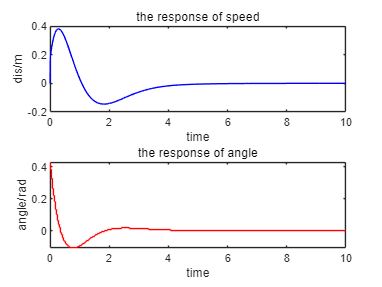

Q_eq = Jz*M + (Jz+M*l*l) * (2*m+(2*I)/r^2);
% A为系统矩阵
A_23=-(M^2*l^2*g)/Q_eq;
A_43=M*l*g*(M+2*m+(2*I/r^2))/Q_eq;  
A = [0 1 0 0;
0 0 A_23 0;
0 0 0 1;
0 0 A_43 0];
% B为输入矩阵
B_21=(Jz+M*l^2+M*l*r)/Q_eq/r;
B_41=-((M*l/r)+M+2*m+(2*I/r^2))/Q_eq;
B = [0 ;
2*B_21;
0 ;
2*B_41];
% C为输出矩阵
C = [0 1 0 0;
0 0 1 0];
D = [0;0];
%定义两组采样时间
Ts = 0.01;
%根据公式计算；
%Fd_1 = expm(A*Ts_1)
%Gd_1 = pinv(A)*(Fd_1-eye(size(Fd_1)))*B
sys_continuous=ss(A,B,C,D);
sys_discrete=c2d(sys_continuous, Ts, 'zoh');
A_discrete = sys_discrete.A;
B_discrete = sys_discrete.B;
C_discrete = sys_discrete.C;
D_discrete = sys_discrete.D;

% 设计离散时间 LQR 控制器
Q = diag([4 4 6 4]);  % 状态权重矩阵
R = 0.9;      % 输入权重矩阵

[K, S, e] = dlqr(sys_discrete.A, sys_discrete.B, Q, R);

sys_discrete.A=sys_discrete.A-sys_discrete.B*K;

% 初始条件
x0=[0 0 0.43 0];
t_discrete = 0:Ts:10;  % 离散时间向量
[row_count, col_count] = size(t_discrete);
% 创建与 TS 相似的零矩阵
u_discrete = zeros(row_count, col_count);%0输入

[y_discrete, t_discrete, x_discrete] = lsim(sys_discrete, u_discrete, t_discrete,x0);

% 绘制仿真结果
subplot(2, 1, 1);
plot(t_discrete, y_discrete(:,1),'b');
title('the response of speed');
xlabel("time");
ylabel("dis/m");
subplot(2, 1, 2);
stairs(t_discrete, y_discrete(:,2),'r');
title('the response of angle');
xlabel("time");
ylabel("angle/rad");

## **预测跟踪**

u_predict = zeros(row_count, col_count);
sys_discrete=c2d(sys_continuous, Ts, 'zoh')

sys_discrete =
 
  A = 
               x1          x2          x3          x4
   x1           1        0.01   -0.004796  -1.592e-05
   x2           0           1     -0.9689   -0.004796
   x3           0           0       1.062      0.0102
   x4           0           0       12.45       1.062
 
  B = 
             u1
   x1  0.002367
   x2    0.4779
   x3   -0.0289
   x4     -5.84
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
采样时间: 0.01 seconds
离散时间状态空间模型。



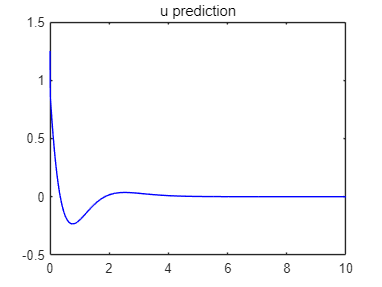

pre=zeros(4,1,1000);
pre(:,:,1)=x0';
u_predict(1,1)=-K*pre(:,:,1);
for i=1:1000
    pre(:,:,i)=sys_discrete.A*pre(:,:,i)+sys_discrete.B*u_predict(1,i); 
    u_predict(1,i+1)=-K*pre(:,:,i);
    pre(:,:,i+1)=pre(:,:,i);
end
%u_predict(1,1)=u_predict(1,2);
figure;
subplot(1, 1, 1);
plot(t_discrete, u_predict(1,:),'b', 'LineWidth', 0.1,'DisplayName', '预测输入');%预测输入
%legend('u');
title('u prediction');

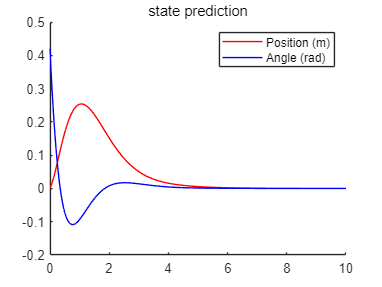


y0=reshape(pre(1,1,:),1,[]);
y1=reshape(pre(3,1,:),1,[]);
y2=reshape(pre(2,1,:),1,[]);
figure;
hold on; 
plot(t_discrete, y0,'r', 'LineWidth', 0.5);%位移
plot(t_discrete, y1,'b', 'LineWidth', 0.5);%倾角
legend('Position (m)', 'Angle (rad)');
title('state prediction');
hold off;

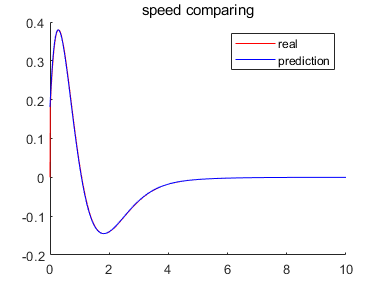


figure;
hold on; 
plot(t_discrete, y_discrete(:,1),'r', 'LineWidth', 0.5);%位移
plot(t_discrete, y2,'b', 'LineWidth', 0.5);%位移
legend('real', 'prediction');
title('speed comparing');
hold off;

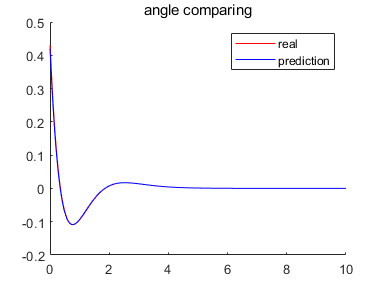


figure;
hold on; 
plot(t_discrete, y_discrete(:,2),'r', 'LineWidth', 0.5);%位移
plot(t_discrete, y1,'b', 'LineWidth', 0.5);%位移
legend('real', 'prediction');
title('angle comparing');
hold off;